## Controlo Automático - Projecto

%% Inicialização do ambiente
clear ; close all; clc

% Importamos os dados dos pacientes
data = importdata('ROC_REAL_50.mat');

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com resultados determinísticos
rng(42);

### **Questão 1**

**a)** Selecionamos 10 pacientes da base de dados:

rndIDX = randperm(50);
sample_size = 10

sample_size = 10

sample = data(rndIDX(1:sample_size), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


t_size = 600

t_size = 600

**b) e c)**

Temos que $(s + \alpha )(s + 4\alpha )(s + 10\alpha ) = s^3 + 15\alpha s^2 + 54\alpha ^2 s + 40\alpha ^3$, o que nos dá os fatores $[1 \ 15a \ 54a^2 \ 40a^3]$.

Cálculo de $c_e \left(t\right)$ e da respectiva média.

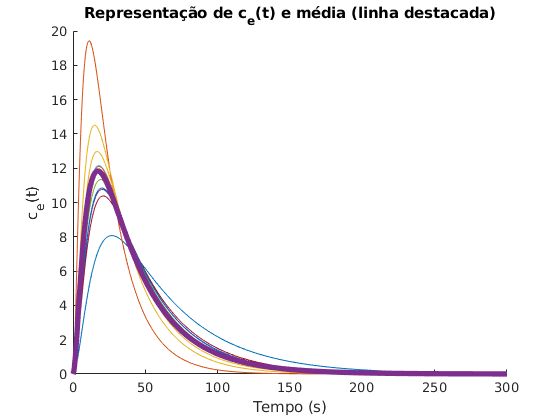

figure(1);
hold on
t = linspace(0, 300, t_size);
Ce = zeros(t_size, sample_size);
G = @(a) tf(40 * a^3, [1 15*a 54*a^2 40*a^3]);
for idx = 1 : sample_size
    a = sample(idx, 1);
    Ce(:, idx) = impulse(G(a) * 600, t);
end
plot(t, Ce);
mean_ce = mean(Ce, 2);
plot(t, mean_ce, 'LineWidth', 4)
xlabel('Tempo (s)')
ylabel('c_{e}(t)')
title('Representação de c_{e}(t) e média (linha destacada)')
hold off

Cálculo de $R\left(t\right)$ e da respectiva média.

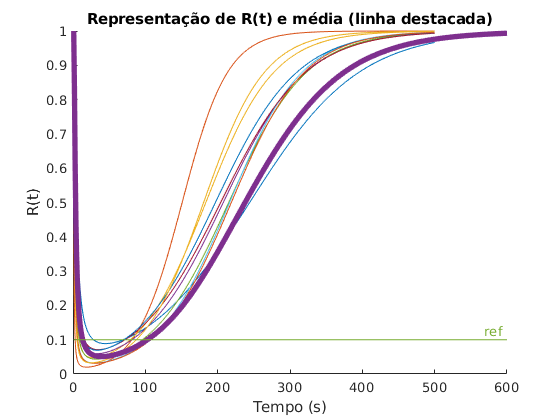

r0 = 1;
EC50 = 1;
figure(2);
hold on
t = linspace(0, 500, t_size);
% O transposto da segunda coluna de `sample` é repetido verticalmente
% `t_size` vezes e multiplicado elemento a elemento com `Ce`
R = r0 ./ (1 + (Ce / EC50) .* repmat(sample(:, 2)', t_size, 1));
plot(t, R);
gamma = mean(R, 2);
plot(gamma, 'LineWidth', 4);
% Ver label.m
label(plot(ones(t_size, 1) * 0.1), 'ref', 'location', 'right');
xlabel('Tempo (s)')
ylabel('R(t)')
title('Representação de R(t) e média (linha destacada)')
hold off

### **Questão 2**

**a)**

Pela condição de estabilidade necessária do critério de estabilidade de Routh-Hurwitz, fácilmente vemos que $\alpha$ tem que ser não negativo, caso contrário pelo menos um dos coeficientes do polinómio do denominador seria negativo. 

Aplicando o método de Routh-Hurwitz obtemos a seguinte tabela:

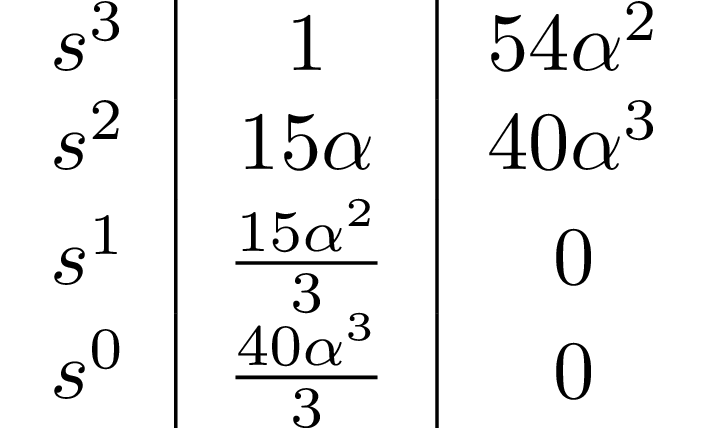

Daqui, fácilmente vemos que os valores da primeira coluna têm todos o mesmo sinal, se $15\alpha > 0$, $\frac{154\alpha^2}{3} > 0$ e $\frac{40\alpha^3}{3} > 0$, o que acontece para todos os $\alpha > 0$, ou seja, para todos os valores estritamente positivos de $\alpha$, o sistema é estável.

**b)**

figure(3);
alpha = mean(sample(:, 2));
constant_infusion = step(G(alpha * 0.6));
step_info = stepinfo(constant_infusion)

step_info = struct with fields:
        RiseTime: 100.8415
    SettlingTime: 186.5193
     SettlingMin: 0.8999
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 334


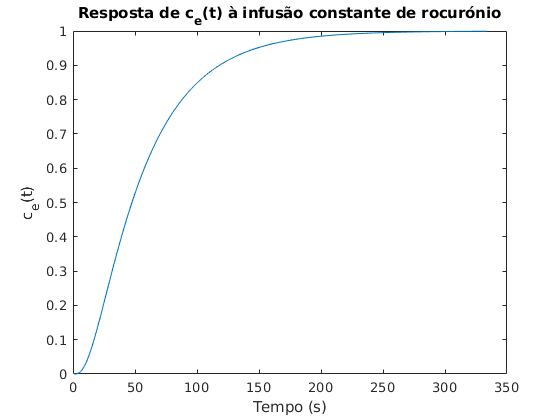

plot(constant_infusion);
xlabel('Tempo (s)');
ylabel('c_{e}(t)');
title('Resposta de c_{e}(t) à infusão constante de rocurónio');